# SDP 02: Graphics and Interaction with the Simple Game Engine

**Learning Objectives:**

By the end of class, your team should be able to:

-   Create and update scenes using the Simple Game Engine (SGE)

-   Use keyboard and/or mouse input to create player interaction

-   Use scene matrices to represent and update game state visually

-   Build one interactive screen for your own SDP game

In this Livescript, work through ONE SECTION AT A TIME. 

**Files that must be in the same folder as this script:**

`  simpleGameEngine.m`

`  retro_pack.png`

`  retro_cards.png             `

`  SGE_workshop_sprite_reference.png`

The main pattern for today is:

      GAME STATE -> DISPLAY -> INPUT -> UPDATE -> DISPLAY AGAIN

## 1. Getting started with the Simple Game Engine                                  

### A. Using Sprites

- The Simple Game Engine uses SPRITES: small images stored in a sprite sheet.

- Every sprite has an ID number. A scene is created by placing those sprite IDs into a MATLAB matrix.

- You do NOT need to memorize sprite numbers. Giving important sprites names makes the rest of the program easier to read.

- Most interactive games are repeated versions of this pattern.


clc
clear
close all

blank_sprite   = 1;      % transparent / empty
wall_sprite    = 555;    % brick wall
player_sprite  = 243;    % blue player
goal_sprite    = 831;    % green target
answer_tile    = 856;    % light square for clickable answers
A_sprite       = 980;
B_sprite       = 981;
C_sprite       = 982;
correct_sprite = 978;
wrong_sprite   = 590;

Open `SGE_workshop_sprite_reference.png` if you want to see these sprites.

### B. Create the SGE scene variable

 The inputs are: `sprite sheet, sprite height, sprite width, zoom, background color`


game_scene = simpleGameEngine('retro_pack.png',16,16,5,[245,245,245]);


### C.  The Screen as a Matrix                                     

A game scene is a MATLAB matrix of sprite IDs.

**IMPORTANT CONNECTION: **MATLAB row/column is equivalent to the screen row/column.

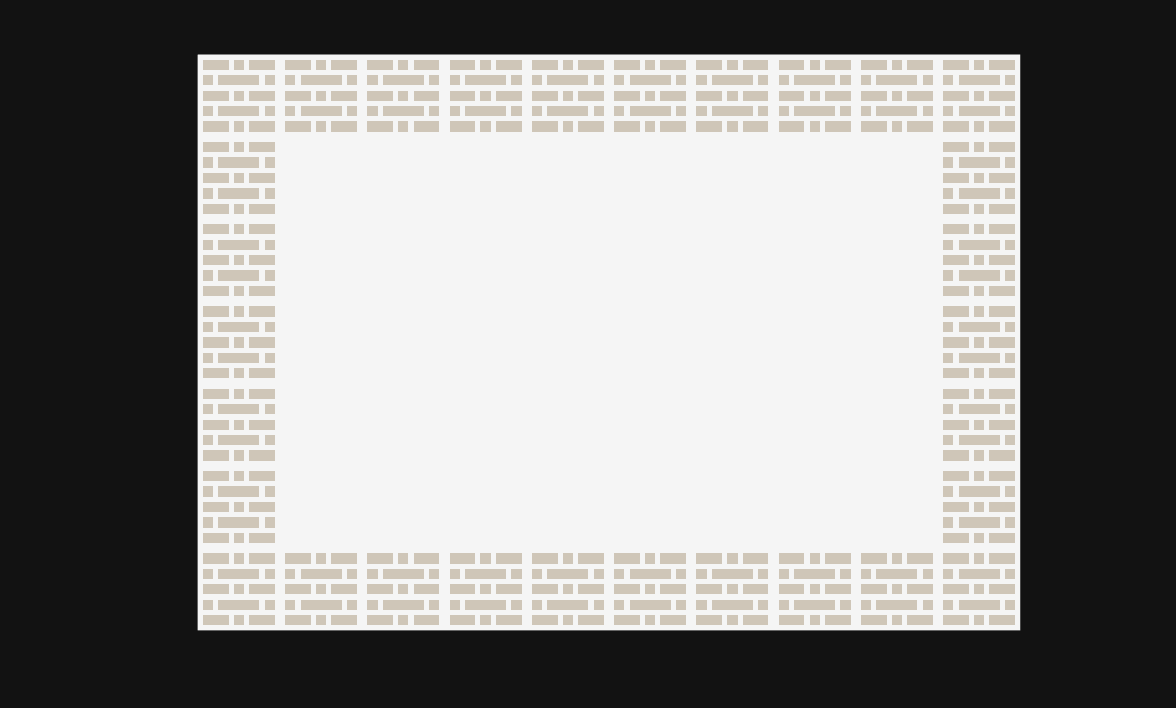

world = [wall_sprite wall_sprite wall_sprite wall_sprite wall_sprite wall_sprite wall_sprite wall_sprite wall_sprite wall_sprite;
         wall_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite wall_sprite;
         wall_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite wall_sprite;
         wall_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite wall_sprite;
         wall_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite wall_sprite;
         wall_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite blank_sprite wall_sprite;
         wall_sprite wall_sprite wall_sprite wall_sprite wall_sprite wall_sprite wall_sprite wall_sprite wall_sprite wall_sprite];

drawScene(game_scene,world)

**IMPORTANT:**

If you change a value in world, MATLAB changes the matrix but the game window will NOT update automatically.

After changing world, run:

`drawScene(game_scene,world)`

to display your updated scene.

#### YOU TRY IT #1

- Change one interior location in world to `player_sprite`.

- Run `drawScene(game_scene,world)` to see the updated scene.

- Change a different interior location to `goal_sprite`.

- Run `drawScene(game_scene,world)` again to see both sprites.

% Type your code here




#### YOU TRY IT #2

- Make sure the `player_sprite` and `goal_sprite` you added in YOU TRY IT #1 have been changed back to `blank_sprite`.

- Now add at least two wall sprites somewhere inside the room by changing specific entries in world.

Do not completely block all paths through the room.

% Write your code below



% Example:
% world(3,5) = wall_sprite;

% Redraw the scene to see your changes.
drawScene(game_scene,world)

## 2. Background and Foreground Layers                           

Games often contain things that stay mostly fixed and things that change.

BACKGROUND examples: floor, walls, paths, rooms

FOREGROUND examples: player, collectible, card, resource, indicator

The SGE can draw two matrices on top of one another.


background = world;

% Determine the number of rows and columns in the game world.
[num_rows,num_cols] = size(background);

% Create an empty foreground that is the same size as the background.
foreground = blank_sprite * ones(size(background));

player_row = 2;
player_col = 2;
goal_row = 6;
goal_col = 9;

foreground(player_row,player_col) = player_sprite;
foreground(goal_row,goal_col) = goal_sprite;

drawScene(game_scene,background,foreground)

**NOTE:**

- `player_row` and `player_col` describe the STATE of the player.

- foreground is one visual representation of that state.

Why might keeping these ideas separate make a larger game easier to build?

## 3. Keyboard Input: Make Something Move                         

`getKeyboardInput` pauses MATLAB until the player presses a key while the game window has focus.

`                key = getKeyboardInput(game_scene)`

Common arrow-key values are: 'uparrow'   'downarrow'   'leftarrow'   'rightarrow'

Now we will use the key to change the player location once. Each time you rerun this section, the player resets to the specific starting location.

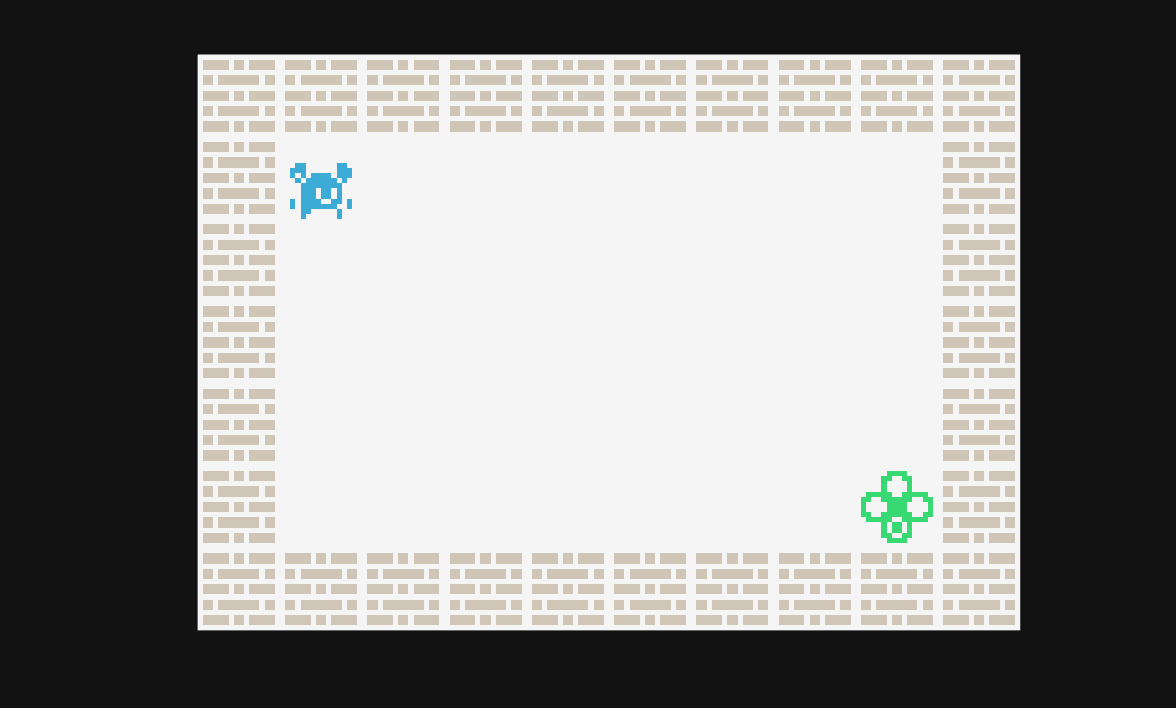


player_row = 4;
player_col = 2;
foreground(:,:) = blank_sprite;
foreground(goal_row,goal_col) = goal_sprite;
foreground(player_row,player_col) = player_sprite;
drawScene(game_scene,background,foreground)


old_row = player_row;
old_col = player_col;

key = getKeyboardInput(game_scene);

if strcmp(key,'uparrow')
    player_row = player_row - 1;
elseif strcmp(key,'downarrow')
    player_row = player_row + 1;
elseif strcmp(key,'leftarrow')
    player_col = player_col - 1;
elseif strcmp(key,'rightarrow')
    player_col = player_col + 1;
end

% A variable changing does NOT automatically change the visualization.
% We must update the foreground and redraw the scene.

foreground(old_row,old_col) = blank_sprite;
foreground(player_row,player_col) = player_sprite;

drawScene(game_scene,background,foreground)

### **Using a Loop to repeat this operation**

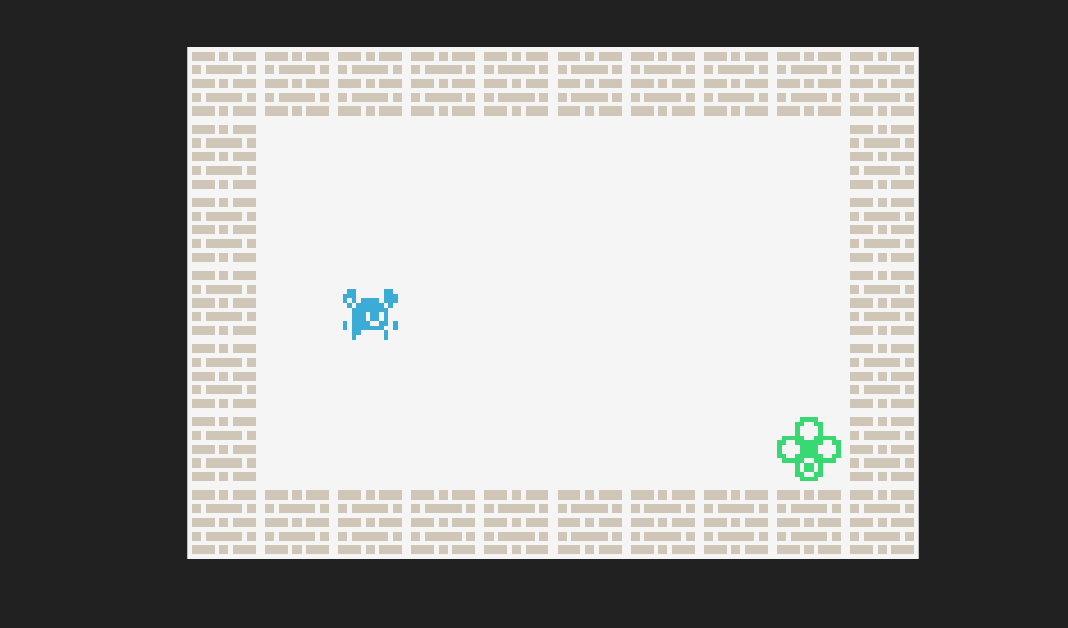


player_row = 4;
player_col = 2;
goal_row = 6;
goal_col = 9;
foreground(:,:) = blank_sprite;
foreground(goal_row,goal_col) = goal_sprite;
foreground(player_row,player_col) = player_sprite;

drawScene(game_scene,background,foreground)

for move = 1:3
    key = getKeyboardInput(game_scene);
    old_row = player_row;
    old_col = player_col;
    if strcmp(key,'uparrow')
        player_row = player_row - 1;
    elseif strcmp(key,'downarrow')

        player_row = player_row + 1;
    elseif strcmp(key,'leftarrow')
        player_col = player_col - 1;
    elseif strcmp(key,'rightarrow')
        player_col = player_col + 1;
    end
    foreground(old_row,old_col) = blank_sprite;
    foreground(player_row,player_col) = player_sprite;
    drawScene(game_scene,background,foreground)

end

**Important:**

- This simple movement example does not check boundaries or collisions. If the player moves beyond the edge of the scene, MATLAB may produce an indexing error. More robust movement checks whether a proposed move is valid before updating the player's position. See the Appendix for an example.

## 4. Mouse Input: Clicking Something                           

- `getMouseInput` returns the ROW and COLUMN that the player clicks.

- The SGE tells your program WHERE the player clicked.

- Your program then decides what that location means.

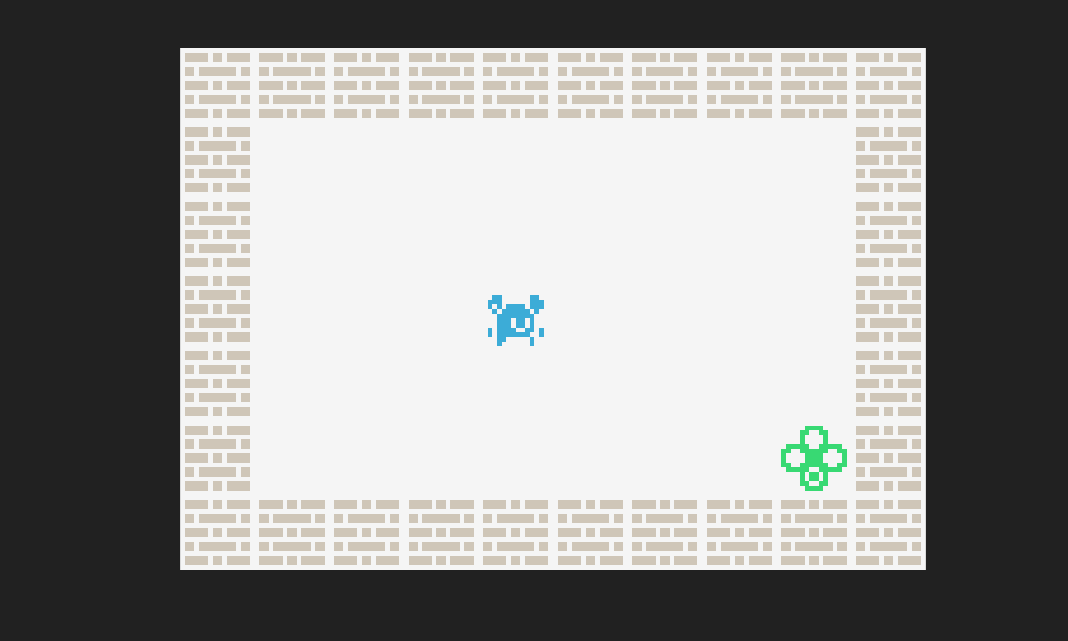


click_scene = simpleGameEngine('retro_pack.png',16,16,7,[245,245,245]);

click_bg = answer_tile * ones(3,3);
click_fg = blank_sprite * ones(3,3);

drawScene(click_scene,click_bg,click_fg)

disp("Click any square in the 3 by 3 scene.")
[row_clicked,col_clicked] = getMouseInput(click_scene);

disp("You clicked row" +row_clicked +", column " + col_clicked)

% Show the target sprite at the selected location.
click_fg(row_clicked,col_clicked) = goal_sprite;
drawScene(click_scene,click_bg,click_fg)

#### YOU TRY IT #3

Right now, the program allows the player to click ONE location and reveal a sprite.

Modify the code so the player can repeat this process three times.

Your program should:

-   Use a loop to allow the player to make 3 selections.

-   Wait for the player to click a location.

-   Change the selected location to `goal_sprite`.

-   Redraw the scene so the player can see the revealed sprite.

-   Pause briefly.

-   Change that location in `click_fg` back to `blank_sprite. `

-   Redraw the scene . Because `click_fg` is blank at that location, the `answer_tile` in the background will appear again

**HINT:**

- the `pause` command can be used to temporarily pause the code's execution

% Include your code here

click_scene = simpleGameEngine('retro_pack.png',16,16,7,[245,245,245]);

Click any square in the 3 by 3 scene.



click_bg = answer_tile * ones(3,3);
click_fg = blank_sprite * ones(3,3);

drawScene(click_scene,click_bg,click_fg)

disp("Click any square in the 3 by 3 scene.")
[row_clicked,col_clicked] = getMouseInput(click_scene);

for iter = 1:3
    [row_clicked,col_clicked] = getMouseInput(click_scene);

You clicked row2, column 2


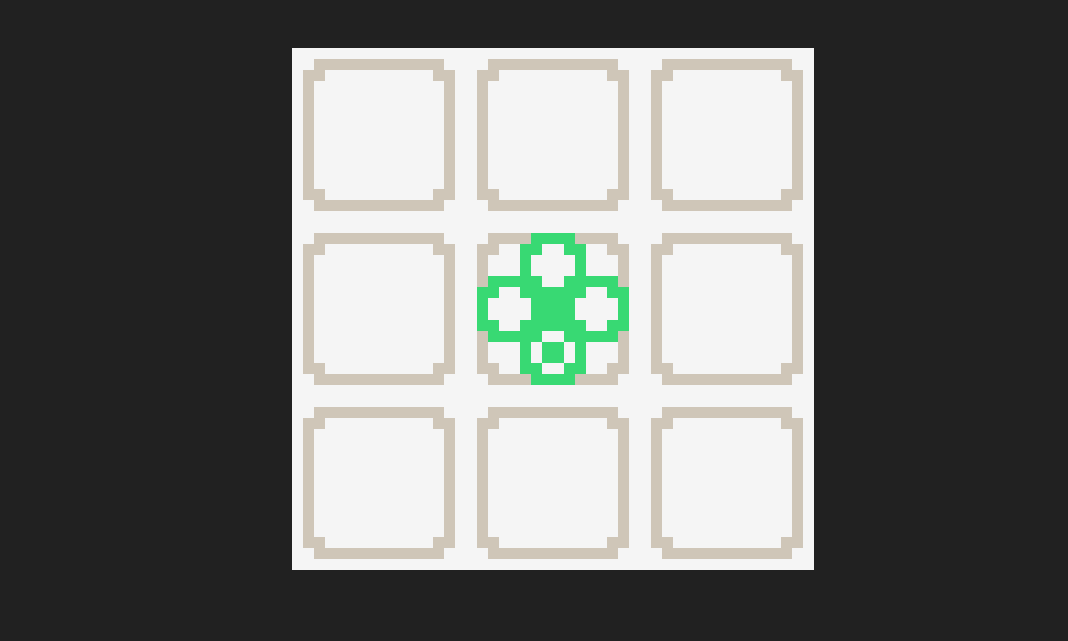


    disp("You clicked row" +row_clicked +", column " + col_clicked)

    click_fg(row_clicked, col_clicked) = goal_sprite;

    drawScene(click_scene, click_fg, click_bg);

    pause(1);

    click_fg(row_clicked, col_clicked) = blank_sprite;
    drawScene(click_scene, click_fg, click_bg);
end


## 5. Pulling It Together: The Game Loop                          

**You have now seen the basic parts of an interactive game:**

-   CREATE a scene

-   DISPLAY the current game state

-   GET player input

-   UPDATE the state

-   CHECK what happens next

-   REPEAT

A generic game structure might look like the following:

`  game_over = false;`

`  while ~game_over`

`      drawScene(...)`

`      Get player input`

`      Interpret the input`

`      Update game-state variables`

`      Check progress / ending condition`

`  end`

This exact structure may not make sense for every game.

The idea is that games and interactive programs repeatedly respond to player actions by changing state and updating what the player sees.

## 6. SDP 02 Post Lab: Start Your SDP 02 Prototype            

Stop following the class example here. Work with YOUR TEAM and YOUR GAME.

Your goal is to create a MINIMUM INTERACTIVE PROTOTYPE containing all three elements below:

-   ONE screen from your actual SDP game

-   ONE meaningful player interaction

-   ONE visible change caused by that interaction

**Examples:**

-   click an answer -> receive feedback

-   move a player -> collect an item

-   choose a resource -> available resources change

-   click an object -> reveal information

-   make a decision -> game status changes

Start writing your code on a separate script file. 

## Appendix -  Prevent Illegal Moves: Boundaries and Collision            

Our previous movement code immediately changed the player's position.

That can allow the player to move into a wall or outside the scene.

To be more robust a better pattern can be the following:

-   PROPOSE a new location

-   CHECK whether that location is allowed

-   ACCEPT the move only if it is valid

% Make sure the starting and goal locations are open.
background(2,2) = blank_sprite;
background(6,9) = blank_sprite;

[num_rows,num_cols] = size(background);
player_row = 2;
player_col = 2;

foreground(:,:) = blank_sprite;

Click any square in the 3 by 3 scene.


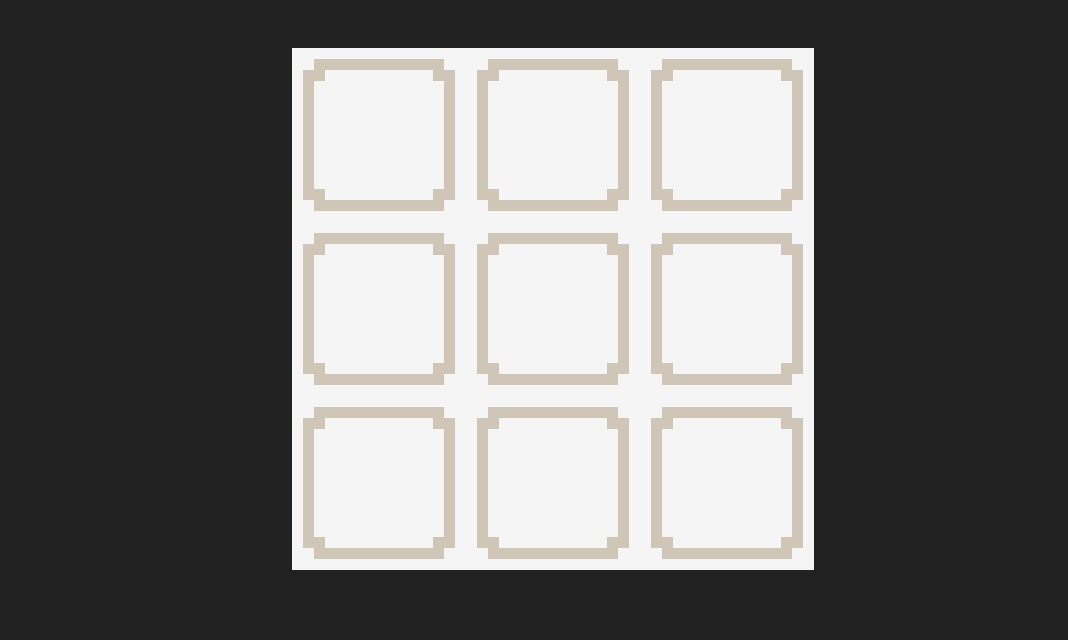

You clicked row2, column 2
You clicked row3, column 3
You clicked row1, column 3


foreground(goal_row,goal_col) = goal_sprite;
foreground(player_row,player_col) = player_sprite;
drawScene(game_scene,background,foreground)

disp("Use arrow keys to move. Press ESC to stop.")

keep_moving = true;

while keep_moving

    key = getKeyboardInput(game_scene);

    candidate_row = player_row;
    candidate_col = player_col;


    if strcmp(key,'uparrow')
        candidate_row = player_row - 1;
    elseif strcmp(key,'downarrow')
        candidate_row = player_row + 1;
    elseif strcmp(key,'leftarrow')
        candidate_col = player_col - 1;
    elseif strcmp(key,'rightarrow')
        candidate_col = player_col + 1;
    elseif strcmp(key,'escape')
        break
    end

    inside_board = candidate_row >= 1 && candidate_row <= num_rows && ...
        candidate_col >= 1 && candidate_col <= num_cols;

    % Only accept a move that is inside the scene and not a wall.
    if inside_board && background(candidate_row,candidate_col) ~= wall_sprite
        player_row = candidate_row;
        player_col = candidate_col;
    end

    % Rebuild the foreground from the CURRENT game state.
    foreground(:,:) = blank_sprite;
    foreground(goal_row,goal_col) = goal_sprite;
    foreground(player_row,player_col) = player_sprite;

    drawScene(game_scene,background,foreground)

    if player_row == goal_row && player_col == goal_col
        disp("Target reached!")
        keep_moving = false;
    end
end


The same "propose -> check -> accept" idea could determine whether:

- a player has enough resources to make a choice

- a card has already been selected

- an answer is valid

- an item is available to collect

- a location is unlocked

## Appendix: Build a World with Nested Loops                            

Typing every tile by hand works for a tiny scene, but it becomes tedious for larger worlds. Nested loops allow us to inspect every row/column location and decide what belongs there.

We will build a 7-by-10 room with walls around the outside.


num_rows = 7;
num_cols = 10;

world = blank_sprite * ones(num_rows,num_cols);

for row = 1:num_rows
    for col = 1:num_cols

        % The condition below checks whether the current location is on
        % any of the four outside edges of the matrix.

        is_edge = row == 1 || row == num_rows || col == 1 || col == num_cols;
        

Use arrow keys to move. Press ESC to stop.


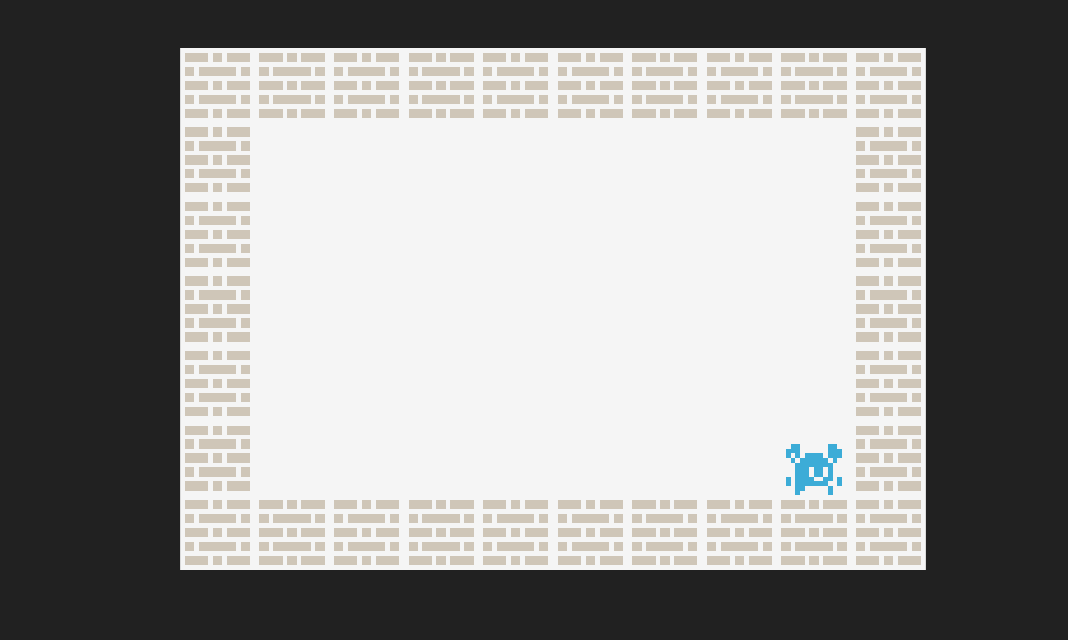

Target reached!


        if is_edge
            world(row,col) = wall_sprite;
        end
    end
end
drawScene(game_scene,world)

% Add two interior barriers so the movement example is more interesting.
world(3,4:6) = wall_sprite;
world(5,6:8) = wall_sprite;

drawScene(game_scene,world)

 **CHECK YOUR WORK:**

- Are all four outside edges walls?

- Is the inside mostly open?

**OPTIONAL YOU TRY IT**

Add one additional obstacle or pattern inside the room. You may either:

- change specific matrix entries, OR

- use the row/column values inside the nested loops.

Do not completely block all paths through the room.

% Write your code below


## Appendix: Card Based Memory Game Mechanic

% Complete this only if your team has finished the required SDP 02 prototype
% or if a matching/memory mechanic is directly useful for your game.
%
% This combines randomization, matrices, repeated mouse input, conditionals,
% and persistent game state.

card_scene = simpleGameEngine('retro_cards.png',16,16,8,[0,120,0]);
card_back = 4;

% Three faces duplicated to create three matching pairs.
card_faces = [21 22 23 21 22 23];
card_faces = card_faces(randperm(length(card_faces)));
card_values = reshape(card_faces,2,3);

% What the player currently sees.
display_cards = card_back * ones(2,3);

% Remember which cards have already been permanently matched.
matched = false(2,3);

matches_found = 0;
attempts = 0;

drawScene(card_scene,display_cards)

while matches_found < 3

    disp("Choose your first card.")
    [row1,col1] = getMouseInput(card_scene);

    while matched(row1,col1)
        disp("That card is already matched. Choose another.")
        [row1,col1] = getMouseInput(card_scene);
    end

    display_cards(row1,col1) = card_values(row1,col1);
    drawScene(card_scene,display_cards)

    disp("Choose your second card.")
    [row2,col2] = getMouseInput(card_scene);

    while matched(row2,col2) || (row2 == row1 && col2 == col1)
        disp("Choose a different unmatched card.")
        [row2,col2] = getMouseInput(card_scene);
    end

    display_cards(row2,col2) = card_values(row2,col2);
    drawScene(card_scene,display_cards)

    attempts = attempts + 1;

    % OPTIONAL YOU TRY IT - IMPORTANT:
    % Complete the condition below BEFORE running this section.
    %
    % Replace false with a condition that determines whether the two selected
    % cards contain the same value.
    if false
        matched(row1,col1) = true;
        matched(row2,col2) = true;
        matches_found = matches_found + 1;
        disp("Match! " + matches_found + " of 3 pairs found.")
    else
        disp("No match")
        pause(1)
        display_cards(row1,col1) = card_back;
        display_cards(row2,col2) = card_back;
    end

    drawScene(card_scene,display_cards)
end

disp("You found all three pairs in " + attempts + " attempts.");

Choose your first card.


Choose your second card.


No match


Choose your first card.


Choose your second card.


No match


Choose your first card.


Choose your second card.


No match


Choose your first card.


Choose your second card.


No match


Choose your first card.


Choose your second card.


No match


Choose your first card.


Choose your second card.


No match


Choose your first card.


Choose your second card.


No match


Choose your first card.


Choose your second card.


No match


Choose your first card.
